# Add Text to a Presentation

Use an `mlreportgen.ppt.Text` object to add text to a presentation. This example uses `mlreportgen.ppt.Text` objects to add text to the title of one slide and the content of another slide.

Create a presentation.

import mlreportgen.ppt.*
ppt = Presentation("myTextPresentation.pptx");
open(ppt);

Add two slides to the presentation.

slide1 = add(ppt,"Title Slide");
slide2 = add(ppt,"Title and Content");

Create an `mlreportgen.ppt.Paragraph` object to use for the title of the presentation.

p1 = Paragraph;

Create an `mlreportgen.ppt.Text` object with bold and red content, and append it to the paragraph.

titleText = Text("My Presentation Title");
titleText.Bold = true;
titleText.FontColor = "red";
append(p1,titleText);

Replace the title in the first slide with the paragraph.

replace(slide1,"Title",p1);

Create a paragraph for the content of the second slide.

 p2 = Paragraph("My content");
 append(p2,Text(" for the second slide"));

Replace the content in the second slide with the paragraph.

 replace(slide2,"Content",p2);

Close and view the presentation.

close(ppt);
rptview(ppt);

Here are the slides in the generated presentation:

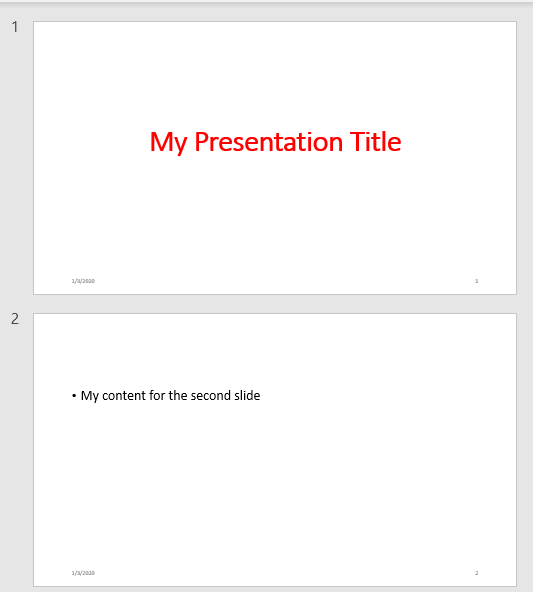

*Copyright 2019 The MathWorks, Inc.*